clc; clear; close all;

%% Path mapping
% Select folder
rootdir = 'E:\TP_EF0050_impulse\Results\TP_EF0050_1p1p50_260425';

% Select file name to load
loadfile = 'PhaseSpeed.mat';

% Select file name to save
% savefile = 'PachyTopoData.mat';

%% Define experimental data
% Define experiment variables keys
% vars_keys = {'FQ', 'ST', 'r'}; % [Frequencies, Strain, Repetition]
% vars_keys = {'FQ', 'r'}; % [Period, Repetition]
vars_keys = {'TP', 'r'}; % [Period, Repetition]

% Define experiment variables and values
variables = {    
    ... % {'1000Hz', '2000Hz', '3000Hz', '4000Hz', '5000Hz'}, ...   % Frequencies
    {'112us','254us'}, ...
    {'1','2','3'}, ...                        % Repetition
};

% Variables to extract from each .mat file
vars_to_save = {'AnglesAll', 'PhaseSpeed_New', 'Thickness_New', ...
    'freq_disp', 'FFT_time_disp', 'Speed_disp'};

%% Summarize processed data
experiment = buildExperimentData( ...
    rootdir, ...
    loadfile, ...
    vars_keys, ...
    variables, ...
    vars_to_save ...
);

    {'112us'}    {'1'}

    {'112us'}    {'2'}

    {'112us'}    {'3'}

    {'254us'}    {'1'}

    {'254us'}    {'2'}

    {'254us'}    {'3'}



experiment = alignExperimentFrequencyGlobal(experiment);

% Summarize Experiment Repetitions
fields_cell_vectors  = {'freq_disp', 'FFT_time_disp', 'Speed_disp'};
fields_angle_vectors = {'Thickness_New', 'PhaseSpeed_New'};
fields_copy          = {'AnglesAll'};

experiment = summarizeExperimentRepetitions( ...
    experiment, ...
    fields_cell_vectors, ...
    fields_angle_vectors, ...
    fields_copy);

% Summarize Experiment Along Angles (After Repetitions)
fields_cell_vectors  = {'freq_disp', 'FFT_time_disp', 'Speed_disp'};
fields_angle_vectors = {'Thickness_New', 'PhaseSpeed_New'};
fields_copy          = {'AnglesAll'};

experiment = summarizeExperimentAngles( ...
    experiment, ...
    fields_cell_vectors, ...
    fields_angle_vectors, ...
    fields_copy);

plotExperimentPhaseSpeedPolarSummary(experiment, rootdir);

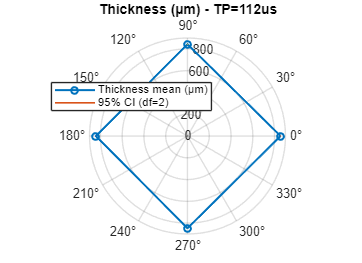

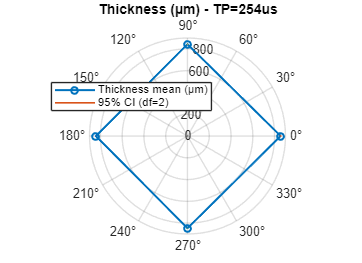

plotExperimentThicknessPolarSummary(experiment, rootdir);

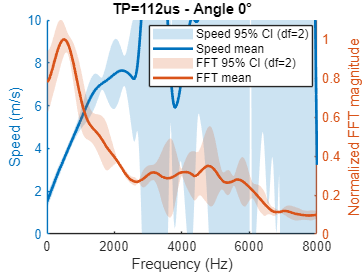

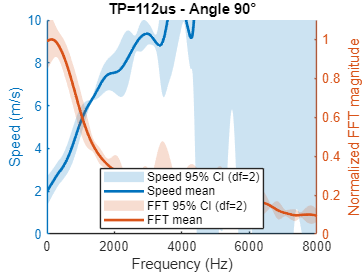

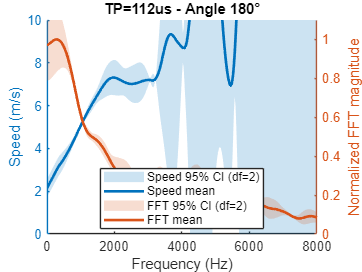

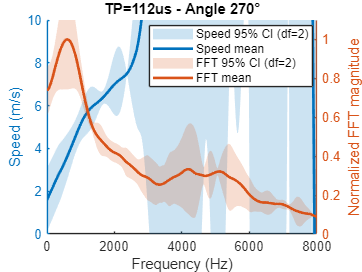

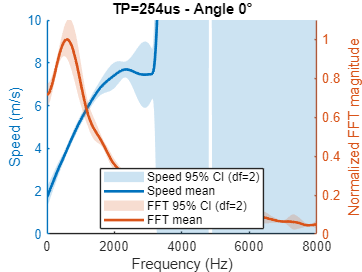

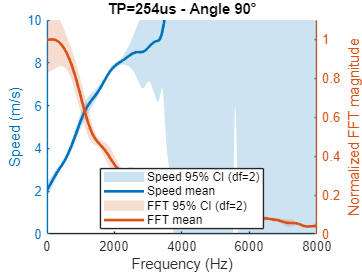

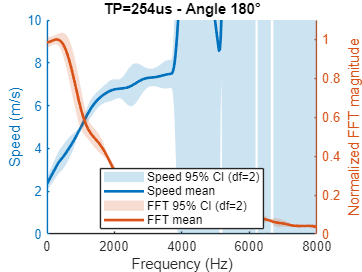

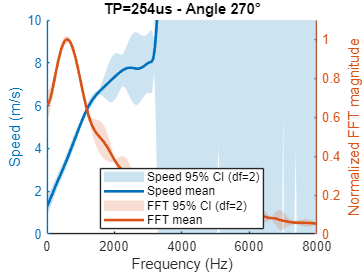

plotExperimentRepetitionDispersionSummary(experiment, rootdir);

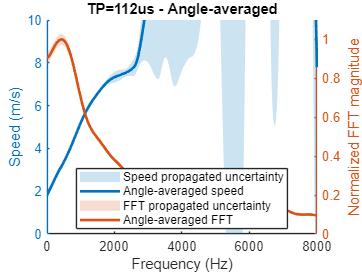

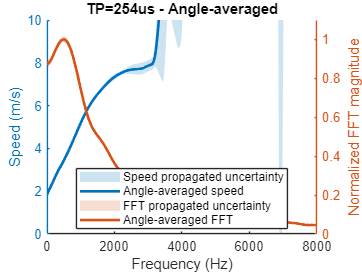

plotExperimentAngleDispersionSummary(experiment, rootdir);

plotPhaseSpeedVsFrequencyByAngle(experiment, rootdir);

Error using plotPhaseSpeedVsFrequencyByAngle>findFrequencyDimension (line 132)
No valid frequency key found. This function requires "FQ".

Error in plotPhaseSpeedVsFrequencyByAngle (line 19)
freqDim = findFrequencyDimension(experiment.vars_keys);


plotPhaseSpeedVsFrequencyAngleAveraged(experiment, rootdir);

save('summary.mat','experiment')

for i = 1:size(experiment.data,1)
    figure();
    ylim([0 15]);
    hold on;
    for j = 1:size(experiment.data,2)
        plot(str2double(experiment.variables{1,2,1}{j}),experiment.data{i,j,1}.PhaseSpeed_New(3),'bx');
    end

    title(['Phase speed (m/s) @ ', num2str(experiment.variables{1,1,1}{i})]);
    grid on;
    hold off;
end

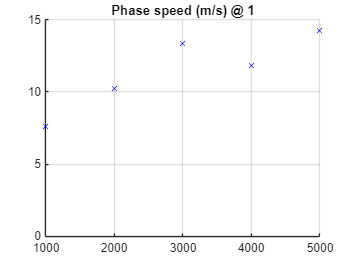

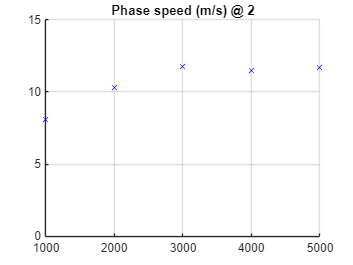

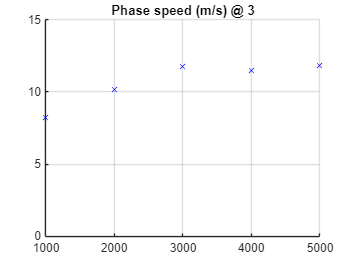

v = size(experiment.data);

for i = 1:size(experiment.data,2)
    figure();
    ylim([0 15]);
    hold on;
    for j = 1:size(experiment.data,1)
        plot(str2double(experiment.variables{1,1,1}{j}(1:4)),experiment.data{j,i,1}.PhaseSpeed_New(3),'bx');
        v(i,j) = experiment.data{j,i,1}.PhaseSpeed_New(3);
    end

    title(['Phase speed (m/s) @ ', num2str(experiment.variables{1,2,1}{i})]);
    grid on;
    hold off;
end

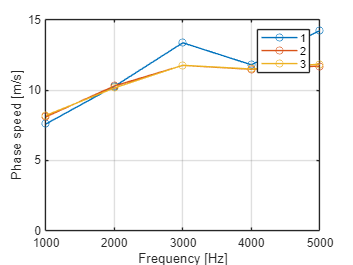


figure()
plot(cellfun(@(x) str2double(erase(x,'Hz')), experiment.variables{1,1,1}), v.','o-')
leyend = cellfun(@(x) x, experiment.variables{1,2,1}, 'UniformOutput', false);
ylim([0 15])
xlabel('Frequency [Hz]');
ylabel('Phase speed [m/s]');
legend(leyend, 'Location', 'northeast');
grid('on');

h = size(experiment.data);

for i = 1:size(experiment.data,1)
    figure();
    ylim([0.53 0.62])
    hold on;
    for j = 1:size(experiment.data,2)
        plot(str2double(experiment.variables{1,2,1}{j}),experiment.data{i,j,1}.Thickness_New(1),'rx');
        h(i,j) = experiment.data{i,j,1}.Thickness_New(1);
    end

    title(['Thickness (mm) @ ', num2str(experiment.variables{1,1,1}{i})]);
    xlabel('Strain [%]');
    ylabel('Thickness [mm]')
    grid on;
    hold off;
end

h_st = mean(h)

figure()
plot(str2double(experiment.variables{1,2,1}), h.','x')
leyend = experiment.variables{1,1,1};
xlabel('Strain [%]');
ylabel('Thickness [mm]');
legend(leyend, 'Location', 'northeast');
grid('on');